## **Jared Ham**

**Mech 513 - HW3**

**Airfoil CFD vs Thin Airfoil Theory vs Experimental Data**

ans = 2

ans = 5

ans = 2

 
S:\GitHub\MECH513-SimAndModeling>xfoil  0<XFOIL_RUN.txt 1>out.txt  


ans = 'PolarNACA0021.txt'

fid = 3

ans = 0

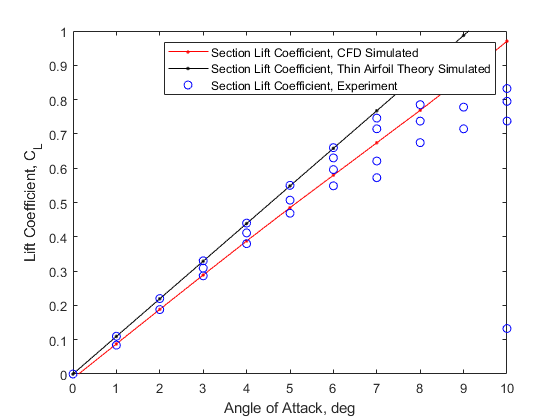

MECH513_ValidationLab; %run to generate and load TAS, Xfoil and Experimental data into workspace

**Task 2 Homework**

To start out, analyze the experimental data that you have.  You should present:

- The regression coefficients for the experimental dataset, and the square of the regression coefficient (R2).  You can choose any regression that you see fit, as long as it goes through [0,0].  

- The standard deviation of the residuals of the regression (*s*)

- Mean and variance of the input values 

- Calculate* SCI*(*x*), and plot the regression of the experimental data plus *SCI, *and minus *SCI* over a relevant range of AoA. 

n = length(Exp_CL)

n = 40

n = 10

n = 10

alpha = 0.1;
[Exp_linear_fit,Exp_linear_fit_gof] = fit(Exp_AoA, Exp_CL, 'poly1', 'Lower', [-Inf 0], 'Upper', [Inf 0]);
Slope = Exp_linear_fit.p1

Slope = 0.0955

Below the y_intercept of the fit is shown to be 0, this is a result of forcing the fit through [0,0]

y_intercept = Exp_linear_fit.p2

y_intercept = 0

The $R^2$ value returned by the 1st order polynomial fit is shown below. 

rsquare = Exp_linear_fit_gof.rsquare

rsquare = 0.9644

residuals_squared = ((Exp_AoA * Slope) - Exp_CL).^2

residuals_squared =          0
    0.0002
    0.0008
    0.0019
    0.0033
    0.0052
    0.0075
    0.0060
    0.0040
    0.0001


s = sqrt(1/(n-1) * sum(residuals_squared))

s = 0.1053

x_bar = mean(Exp_AoA)

x_bar = 4.5000

s_x = std(Exp_AoA);
x_variance = s_x^2

x_variance = 8.4615

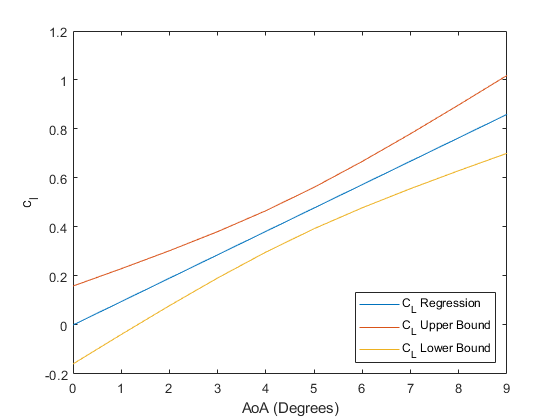

F_value = finv(1-alpha, 2, n-2);
SCI = s * sqrt(2*F_value*(1/n + (Exp_AoA - x_bar).^2 ./ ((n-1)*s_x^2)));
figure
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope)
hold on;
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope + SCI(1:10))
plot(Exp_AoA(1:10), Exp_AoA(1:10) * Slope - SCI(1:10))
ylabel({'c_l'});
xlabel({'AoA (Degrees)'});
legend1 = legend('show');
legend({'C_L Regression','C_L Upper Bound','C_L Lower Bound'},'location','southeast')
hold off;

Figure 1: Linear Regreesion of Experimental $c_l$ vs AoA plotted with upper and lower confidence intervals

Question 2: Begin with the thin airfoil simulation. 

- Calculate the average relative error (one number)

- Calculate the simultaneous confidence indicator (one number)

- Present the average relative error and CI (*XX% ± ZZ% with 90% confidence)* as our validation metric to represent error across the entire domain. 

To calculate the average relative error only AoAs that we have data for and where Cl is non zero need to be examined, this is AoA 1 thru 9. 

Exp_CL_mult_columns = [Exp_CL(2:10) Exp_CL(12:20) Exp_CL(22:30) Exp_CL(32:40)]

Exp_CL_mult_columns =     0.1100    0.1100    0.1100    0.0842
    0.2200    0.2200    0.2200    0.1879
    0.3300    0.3300    0.3088    0.2861
    0.4400    0.4400    0.4114    0.3800
    0.5500    0.5500    0.5068    0.4687
    0.6600    0.6299    0.5960    0.5486
    0.7460    0.7150    0.5724    0.6209
    0.8274    0.7851    0.7373    0.6745
    0.8527    0.8311    0.7781    0.7148


y_bar_Experiment = mean(Exp_CL_mult_columns,2);
E_TAS = 1/range(TAS_AoA(2:10)) * sum(abs((TAS_CL(2:10) - y_bar_Experiment) ./ y_bar_Experiment))

E_TAS = 0.1112

average_CI_TAS = 1/range(TAS_AoA) * sum(abs(SCI(2:10) ./ y_bar_Experiment))

average_CI_TAS = 0.3194

With 90% confidence, the average relative error and CI of the thin airfoil theory model is 11.2% $\pm$ 6.7%

Question 3: Same as Question 2 but with CFD instead of TAS

E_CFD = 1/range(CFD_AoA(2:10)) * sum(abs((CFD_CL(2:10) - y_bar_Experiment) ./ y_bar_Experiment))

E_CFD = 0.0816


average_CI_CFD = 1/range(CFD_AoA) * sum(abs(SCI(2:10) ./ y_bar_Experiment))

average_CI_CFD = 0.3194

With 90% confidence, the average relative error and CI of the XFOIL CFD model is 8.2% $\pm$ 6.7%

**Conclusion: **Based on average relative error and CI of the thin air foil theory model vs the CFD model, it can be concluded that the CFD model more closely predicts the results of the experiment than the thin air foil theory model. 

**Other Things to Note: **It is likely that the numerically calculated average relative error for both the thin air foil model and CFD model would be improved if a trapezoidal integration method was used. But for the purposes of comparing two models, using a rectangular numerical integration technique will suffice. In reality the average relative errors are likely slightly smaller than what was calculated since the rectangular integration method used over predicted the integral. 

For completeness, I reran the average relative error and the average CI calcs below using trapezoidal integration instead of rectangular. 

Q2:

E_TAS = 1/range(TAS_AoA(2:10)) * trapz(abs((TAS_CL(2:10) - y_bar_Experiment) ./ y_bar_Experiment))

E_TAS = 0.0924

average_CI_TAS = 1/range(TAS_AoA) * trapz(abs(SCI(2:10) ./ y_bar_Experiment))

average_CI_TAS = 0.2445

Q3:

E_CFD = 1/range(CFD_AoA(2:10)) * trapz(abs((CFD_CL(2:10) - y_bar_Experiment) ./ y_bar_Experiment))

E_CFD = 0.0664


average_CI_CFD = 1/range(CFD_AoA) * trapz(abs(SCI(2:10) ./ y_bar_Experiment))

average_CI_CFD = 0.2445

As you can see, the relative error and the average CI both dropped slightly for both cases. 